clc
clear


## Constants

% General Constants %
Lt = meterToFeet(19.06); % Moment Arm of the Wing-Tail 
Nz =3.75; % Ultimate Load Factor (1.5*Limit Load Factor) BIG ASSUMPTION !!! XD
Wdg = kgToPounds(90030); % Design Gross Weight [lb]
L_D = 18.6;
W_c = kgToPounds(17850) % Weight of the cargo (lbs)
N_p = 170 + 5 % Number of personal (crew + passangers)


W_c = 3.9352e+04

N_p = 175

% Wing Constants %
ARwing = obj.AR % ARWing = 12.7; % Aspect Ratio (Wing)
TaperRatio = obj.TR % = 0.18; % Taper Ratio
c_Scsw =0.1 % Coefficient of size of control surface of wing to actual wing size ASSUMPTION MAY NOT BE NEEDED ONCE EVLEVATOR AREA KNOWN !!! (feet)^2
Sw_meter = obj.WingArea % Sw_meter =  124.7;  %Surface area of the wing
Sw = m2toft2(Sw_meter); % Trapezoidal Wing Area [ft^2]

c_Scsw = 0.1000

Scsw = c_Scsw * Sw; % Control Surface Area (Wing-Mounted) [ft^2] ASSUMPTION
SweepWingQuarter = obj.SweepAngle % = 25; % Wing Sweep at 25% MAC 
SweepWingQuarter_rad = deg2rad(SweepWingQuarter);% Wing Sweep at 25% MAC RAD
obj.t_c = t_c % = 0.14; % Thickness to chord ratio ASSUMED FOR ALL SURFACES CURRENTLY
b_w = mToFt(obj.WingSpan) % Wing span (feet)
thicknessTaperRatio = 0.2 %CHECK THIS 07/04/26
obj.rootChord = rootChord % 5.3 Root chord length (meters)

b_w = 130.9055

tipChord = rootChord*TaperRatio; % Tip chord length (meters)

thicknessTaperRatio = 0.2000

obj.dihedralAngle = dihedralAngle % 5.5; % Dihedral angle (degrees)
dihedralAngleRad = deg2rad(dihedralAngle);
%cgPercentageMAC = 50; % LOL WTF WAS THIS ??? CG location as a percentage of MAC (e.g., 0.35 for 35%)
Cmac = (2/3) * rootChord * ((1 + TaperRatio + TaperRatio^2) / (1 + TaperRatio));
rootThickness = rootChord*t_c % thickness at the root (of the aerofoil) (m)
start_wing = obj.WingPos % Start of the wing from the datum (meter)

Cmac = 4

rootThickness = 1


% Horizontal Tail Constants %
Ah = obj.HAR; % Horizontal tail aspect ratio
Bh_m = obj.HSpan % 11.17 % Tail 
Bh = mToFt(Bh_m); % Span of the Tail (Feet)
Fw = 12; % ASK SANTOSH !!! fusalage width at horizontal tail attachement point(Feet) ASSUMPTION

Bh_m = 11.1700

Kuht = 1.143; % Coefficient using if the tail is swept backwards
Ky = 0.3*Lt; % Radius of gyration of aircraft pitching coefficient relativing the rough distance (0-1) of the fusalage ASSUMPTION
c_Se = 0.3 % Coefficient of size of control surface of tail to actual tail size ASSUMPTION MAY NOT BE NEEDED ONCE EVLEVATOR AREA KNOWN !!! (feet)^2
Sht = m2toft2(obj.HTailArea); % Surface Area tail ft^2
Se = c_Se*Sht; % Area of the Elevators of the tail

c_Se = 0.3000

tail_SweepHorz = obj.HTailSweep % = 34; % (degrees) 
tail_SweepHorzTail_rad = deg2rad(tail_SweepHorz) % (Rad)
tail_dihedral = 0 % degree / rad (Assumed always 0 for tail)
root_tail = obj.HChord % 3.424; 

tail_SweepHorzTail_rad = 0.5934

HT_Taper = obj.HTaperRatio % Horizontal Taper

tail_dihedral = 0

tip_tail = root_tail*HT_Taper; 
tail_Cmac = (2/3) * root_tail * ((1 + HT_Taper + HT_Taper^2) / (1 + HT_Taper));
tail_thicknessTaper = 1 % Dimensionless (Ask Zak later !!!!)
tail_rootThickness = obj.TailRootThick % 0.35 % (m) thickness at the root (of the aerofoil) %
start_tail = obj.TailStartX % 35.26 % Start of the tail from the datum (meter)

tail_thicknessTaper = 1

tail_rootThickness = 0.3500

start_tail = 35.2600

% Vertical Tail Constants %
SweepVertTail = obj.VTailSweep % 38; % (degrees)
Ht_Hv= 0.5; % REVIEW !!!! Height (location) of the horizontal stabalizer relative to the total vertical tail length
Svt = m2toft2(obj.VTailArea); % Vertical tail area (feet^2)
kz = Lt; % Radius of gyration in yaw axis (Mass distributed around vertical Tail) ASSUMPTION FROM RAYMER = Lt
Av = obh.VAR; % Aspect  ratio of the vertical tail
root_vert = obj.VChord % 4.48; % Verical tail root chord (m)
VT_Taper = obj.VTaperRatio % Vertical Tail taper ratio 
tip_vert = VT_Taper*root_vert ; % Vertical tail tip chord (m)
sweepAngle_vert = obj.VTailSweep% 38; % Angle backwards from datum of the tail (degree)
sweepAngle_vert_rad = deg2rad(sweepAngle_vert) % Angle backwards from datum of the tail (rad)
b_Vt = obj.VSpan % 6.05; % Span of the verticle tail (m)
Vtail_rootThickness = obj.VChord % 0.5377 % Vertical fin thickness at root chord (m)

sweepAngle_vert_rad = 0.6632

Vtail_ThicknessTaper = 1 ; % GUESS FIND AN ACTUAL VALUE 
Vtail_tipThickness =  obj.VChord*Vtail_ThicknessTaper% 0.268 % Vertical fin thickness at tip chord (m)

Vtail_rootThickness = 0.5377

Vtail_Cmac = (2/3) * root_vert * ((1 + VT_Taper + VT_Taper^2) / (1 + VT_Taper)); % Verical fin (m)


Vtail_tipThickness = 0.2680

Vtail_ThicknessTaper = 0.4984

VT_Taper = 0.4464


% Fusalage Variables % 

start_wing = 15.5500

k_door = 1.0; % If there is a cargo door then it become > 1 
K_lg = 1.0; % If the landing gear is mounted to the fuselage 1.12
L_f = mToFt(obj.FuselageLength); % Length of the fuselage (feet)
Sf = 0.9*pi*L_f*(mToFt(obj.FuselageDiameter)); % Using Raymer's empirical assumption
V_pr = m3toft3(obj.FuselageVolPressurised) % ASK SANTOSH Volume of the pressurised section RESONABLE ESTIMATE
K_ws = 0.75*((1+(2*TaperRatio))/(1+(TaperRatio))*((b_w*tand(SweepWingQuarter))/(L_f)));


V_pr = 1.2360e+04

% Main Landing gear % - janky as fuck - COME BACK LATERRRR 07/04/26
k_mp = 1; % Raymer - type of LG variable
w_l = kgToPounds(65000); % landing design gross weight
n_l = 3; % ultimate landing load factor
l_m = metersToInches(4.5); % main LG length [ft] - GUESS
N_mw = 4; % no of main wheels - GUESS AGAINNN
N_mss = 2; % no of main gear shock struts - GUESS
CLmax = obj.CLmax % lol guess again
rho = 1.225; % density at sl
Vs_mps = sqrt((2 * Wdg)/(rho * obj.WingArea * CLmax));
Vs_feet_s = mps_to_fps(Vs_mps)
Load_factor = 4.5 % Maximum load factor
Max_main = poundsToKg(w_l) % Max mass capability of main landing gear (kg)

Vs_feet_s = 128.1251

X_length_main = obj.LandingGearPos % 19.55 % Distance from datum to the main gear (m)


Max_main = 9.1126e+04

X_length_main = 19.5500

% Nose Landing gear %
k_np = 1; % Raymer - type of LG variable
l_n = metersToInches(3.5); % nose landing gear length guess from yap gpt
N_nw = 2; % no of nose wheels - change maybe
Max_nose = poundsToKg(2*13889)% Max mass capability of nose landing gear (kg)
X_length_nose =3.98 % Distance from datum to the nose gear(m)


Max_nose = 1.2600e+04

% Fuel center tanks

X_length_nose = 3.9800

Density_kerosene = 800 % kg/m^3
volume_center_tank = 0.8*(5.7*3.2) % Roughly assumed at the moment
mass_center_fuel = volume_center_tank*Density_kerosene % Density_kerosene*volume_center_tank

Density_kerosene = 800

volume_center_tank = 14.5920

% Fuel 

mass_center_fuel = 1000

V_t = 6613.78; % total fuel volume [US gal]
V_i = 6613.78; % integral tank volume [US gal]
V_p = 0; % self-sealing not assumed 
N_t = 2; % No of fuel tanks
N_en = 4; % No of engines
W_fuel =0 % 11500-(mass_center_fuel/2) ; % Mass of fuel in each tank ASSUMPTIONNNN

% Engine

W_fuel = 0

WEngine = obj.EngineWeight; % engine mass [kg]
WEngine_lbs = poundsToKg(WEngine)
% Nacelle group
k_ng = 1 % Becomes 1.017 for a pylon mounted nacelle

WEngine_lbs = 1.3277e+03

Nacelle_length = mToFt(obj.NacelleLength) % Engine nacelle length (feet)
Nacelle_width = mToFt(obj.NacelleWidth) % Engine nacelle width (feet)

k_ng = 1

w_ec = kgToPounds(WEngine) % Total engine mass nacelle etc. (kg)
s_n = m2toft2(obj.NacelleWetted) % Wetted area of the nacelle ft^2

Nacelle_length = 18.0446

Nacelle_width = 8.0381

L_ec = mToFt(obj.EngineLocX) % Distance from the start of the engine to the cockpit

w_ec = 1.0970e+04

s_n = 455.5282

L_ec = 26.2467

% Flight controls
N_f = 7 % Number of functions of the flight controls
N_m = 2 % number pulled out of Raymers ass probably right but i dont care either way its 2
s_cs = Se + Scsw

N_f = 7

x = feetToMeters(223.8)

N_m = 2

I_y = 7e6 % in lb-ft^2 ESTIMATION AT THE MOMENT TO BE DISCOVERED

s_cs = 223.8030

x = 68.2142

% Instruments

I_y = 7000000

K_r = 1 % Should be 1.133 for a piston engine
K_tp = 1 % Should be 0.793 if a turboprop
N_c = 4 % Number of crew not including the pilots

K_r = 1

K_tp = 1

% Electronics

N_c = 5

R_kva = 90 % KVA from the A320 electronics electrical rating 
L_a = L_f
N_gen = N_en

R_kva = 90

L_a = 131.2336

% Avoinics

N_gen = 2

W_uav = 1000 % Taken as an estimation from the raymer book lbs

% Cabin dimensions

W_uav = 1000

Cabin_length = obj.CabinLength; % meters
Cabin_inner_diameter = obj.CabinDiameter % meters
Cabin_inner_height = 2.54 % ASSUMPTION meters
CargoMass = ADP.TLAR.Payload % Max passangers * Avg. weight

Cabin_inner_diameter = 3.8900

Cabin_inner_height = 2.5400

% Storage (Overhead and Below)

Passanger_weight = 17976

% Length_storage_container = inchesToMeters(60.4) % meters
% Height_storage_container = inchesToMeters(45) % meters 
% Width_storage_container = inchesToMeters(96.2) % meters

Length_storage_container = 1.5342

Height_storage_container = 1.1430

% maxCapacity_storage_container = "xxx" % FILL LATER (Kg)

Width_storage_container = 2.4435


% Total_passenger_luggage = 214 * 21 % (21kg of luggage) Currently assumed off the 105kg model total pax 

maxCapacity_storage_container = "xxx"

## Bubble plot

Total_passenger_luggage = 4494

WWing_kg = 6.6209e+03

W_furnishings_kg = 5.2103e+03

W_airConditioning_lbs = 2.0666e+03

W_airConditioning_kg = 937.3747

W_antiIce_lbs = 396.9639

W_antiIce_kg = 180.0596

Plane_no_seats = 3.1366e+04

avionics_instruments = 1.5537e+03

Component weights and labels have been written to component_weights.xlsx


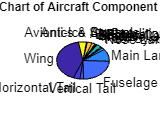

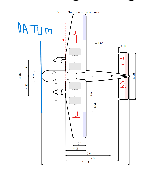

Aerodynamic Centre Location:
  x = 4.574 m
  y = 7.664 m
  Distance to start of the CMAC from LE:
  x = 3.574 m


CG_wing_x_1 = 5.5740

CG_wing_y_1 = 7.6644

CG_wing_z_1 = 1.0380

AC_wing_x = 4.5740

Aerodynamic Centre Location:
  x = 2.296 m
  y = 2.439 m
  Distance to start of the CMAC from LE:
  x = 1.645 m


CG_tail_x_1 = 2.9459

CG_tail_y_1 = 2.4392

CG_tail_z_1 = 0.1750

AC_tail_x = 2.2956

vertTailCG_x = 2.7300

vertTailCG_y = 0

vertTailCG_z = 1.3195

cylinderCG_x = 19.9950

cylinderCG_y = 0

cylinderCG_z = 0

engineCG_x_1 = 1.6300

engineCG_y_1 = 0

engineCG_z_1 = 0

combinedCG_x_1 = 0.0750

combinedCG_y_1 = 0.0750

combinedCG_z_1 = 0.2868

center_CG_fuel_x = 2.5000

center_CG_fuel_y = 0

center_CG_fuel_z = 0.5050

Fuel_coverage = 0.6500

CG_fuel_x_1 = 4.3231

CG_fuel_y_1 = 4.9819

CG_fuel_z_1 = 0.4797

CG_fuel_x_2 = 4.3231

CG_fuel_y_2 = -4.9819

CG_fuel_z_2 = 0.4797

passengerCG_x = 13.5000

passengerCG_y = 0

passengerCG_z = 1.2700

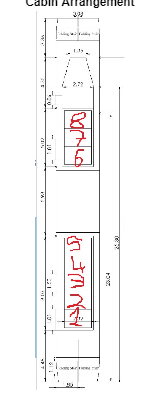

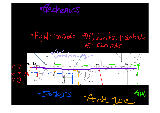

W_payload_container = 685.5603

Total_storage_under = 4.1751e+03

remaining_overhead = 318.9378

ContainerCG_x = 0.7671

ContainerCG_y = 0

ContainerCG_z = 0.5715

APU_x = 1.2000

APU_y = 0.8000

APU_z = 0.8000

APUCG_x = 0.6000

APUCG_y = 0

APUCG_z = 0.4000

Controls_x = 1.5000

Controls_y = 2

Controls_z = 2

ControlsCG_x = 0.7500

ControlsCG_y = 0

ControlsCG_z = 1

AI_x = 0.5500

AI_y = 0.5500

AI_z = 0.5500

AICG_x = 0.2750

AICG_y = 0

AICG_z = 0.2750

Furnishings_x = 0.5000

Furnishings_y = 0.5500

Furnishings_z = 0.5500

FurnishingsCG_x = 13.5000

FurnishingsCG_y = 0

FurnishingsCG_z = 1.2700

AC_x = 1.3000

AC_y = 0.8000

AC_z = 0.7000

ACCG_x = 0.6500

ACCG_y = 0

ACCG_z = 0.3500

Starter_x = 0.6000

Starter_y = 0.3000

Starter_z = 0.3000

Starter_x_1 = 0.3000

Starter_y_1 = 0

Starter_z_1 = 0.1500

Starter_y_1 = 0

Starter_x_2 = 0.3000

Starter_y_2 = 0

Starter_z_2 = 0.1500

Electrical_x = 19.9950

Electrical_y = 0

Electrical_z = 0

ElectricalCG_x = 9.9975

ElectricalCG_y = 0

ElectricalCG_z = 0

Center_fuelCG_local =     2.5000         0    0.5050


cabinCG_local =    13.5000         0    1.2700


Cabin_offset =     4.4200         0    3.7900


ContainerCG_local =     0.7671         0    0.5715


Container_offset_1 =     9.0800         0    2.5200


Container_offset_2 =    10.6142         0    2.5200


Container_offset_3 =    12.1483         0    2.5200


Container_offset_4 =    13.6825         0    2.5200


Container_offset_5 =    15.2166         0    2.5200


Container_offset_6 =    21.2166         0    2.5200


Container_offset_7 =    22.7508         0    2.5200


Container_offset_8 =    24.2850         0    2.5200


APUCG_local =     0.6000         0    0.4000


APU_offset =    37.9000         0    4.0000


controlsCG_local =     0.7500         0    1.0000


controls_offset =     3.5000         0    3.0000


AICG_local =     0.2750         0    0.2750


AI_offset =     25     0     3


ACCG_local =     0.6500         0    0.3500


AC_offset =     25     0     2


FurnishingsCG_local =    13.5000         0    0.5500


Furnishings_offset =     4.4200         0    3.7900


ElectricalCG_local =     9.9975         0         0


Electrical_offset =          0         0    3.7700


StarterCG_local_1 =     0.3000         0    0.1500


Starter_offset_1 =    15.5000    5.6000    1.5200


StarterCG_local_2 =     0.3000         0    0.1500


Starter_offset_2 =    15.5000   -5.6000    1.5200


centerFuel_global =    19.6200         0    2.5050


globalCG_x = 19.2693

globalCG_y = 0.0491

globalCG_z = 3.5461

% Load the image
aircraftImage = imread('side_profile_bubble.png'); % Replace with your image file


% Get the dimensions of the image
[imageHeight, imageWidth] = size(aircraftImage);

% Display the dimensions
fprintf('Image Width: %d pixels\n', imageWidth);
fprintf('Image Height: %d pixels\n', imageHeight);

% Define local CGs and offsets
components = {
    % Format: {Local_CG, Offset, 'Label'}
    {[CG_wing_x_1, CG_wing_y_1, CG_wing_z_1], [start_wing, 2.03, (2.51 - rootThickness)], 'Wing 1'},
    {[CG_wing_x_2, CG_wing_y_2, CG_wing_z_2], [start_wing, -2.03, (2.51 - rootThickness)], 'Wing 2'},
    {[vertTailCG_x, vertTailCG_y, vertTailCG_z], [33.49, 0, 7.67], 'Vertical Tail'},
    {[CG_tail_x_1, CG_tail_y_1, CG_tail_z_1], [start_tail, 2.6, (7.46 - tail_rootThickness)], 'Horizontal Tail 1'},
    {[CG_tail_x_1, CG_tail_y_1, CG_tail_z_1], [start_tail, -2.6, (7.46 - tail_rootThickness)], 'Horizontal Tail 2'},
    {[engineCG_x_1, engineCG_y_1, engineCG_z_1], [17.5, 5.6, 1.52], 'Engine 1'},
    {[engineCG_x_2, engineCG_y_2, engineCG_z_2], [17.5, -5.6, 1.52], 'Engine 2'},
    {[combinedCG_x_1, combinedCG_y_1, combinedCG_z_1], [X_length_main, 3.61, 0], 'Main Gear 1'},
    {[combinedCG_x_2, combinedCG_y_2, combinedCG_z_2], [X_length_main, -3.61, 0], 'Main Gear 2'},
    {[center_CG_fuel_x, center_CG_fuel_y, center_CG_fuel_z], [17.12, 0, 2], 'Center Tank'},
    {[CG_fuel_x_1, CG_fuel_y_1, CG_fuel_z_1], [16.5, 2.03, 3.04], 'Fuel 1'},
    {[CG_fuel_x_2, CG_fuel_y_2, CG_fuel_z_2], [16.5, -2.03, 3.04], 'Fuel 2'}
    % Add additional components as needed...
};

% Loop through components and plot their global CGs (z vs x)
for i = 1:length(components)
    localCG = components{i}{1};
    offset = components{i}{2};
    label = components{i}{3};

    % Calculate global CG in meters (using z and x only)
    globalCG = localCG + offset;

    % Convert to pixel positions (z and x)
    globalCG_px = [globalCG(1), globalCG(3)] * pixelsPerMeter; % X and Z positions
    globalCG_px(2) = imageHeight - globalCG_px(2); % Adjust Z for image coordinate system

    % Plot CG point
    plot(globalCG_px(1), globalCG_px(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Add label
    text(globalCG_px(1) + 10, globalCG_px(2), label, 'Color', 'red', 'FontSize', 10);
end

hold off;


## POH section

## Finding the neutral point

cg_x = 5.5740

cg_z = 1.0380

cg_y = 7.6644

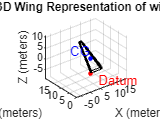

cg_x_tail = 2.9459

cg_z_tail = 0.1750

cg_y_tail = 2.4392

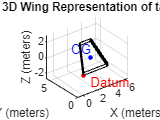

offset_Vtail_root = 0.5377

offset_Vtail_side = 3.5000

Vtip_end = 5.7400

length_taper = 0

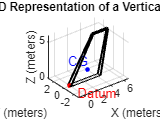

format default
%CLA for tail and wing 
CLaTail = 4.35 % 1/rad


%Found using JavaFoil

CLawing = 5.5 % 1/rad

%Aerodynamic centre of the tail
ACt = AC_tail_x + start_tail;
ACw = AC_wing_x + start_wing

CLaTail = 4.3500

%Distance between COG and Tail AC
Lt = ACt - ACw

vh_prime = (Lt*Sht_meter)/(Sw_meter*Cmac)  

CLawing = 5.5000


deltaEA = (2*CLawing)/(pi*ARWing)

Hn = ACw/Cmac + (vh_prime*(CLaTail/CLawing))*(1-(deltaEA))

ACw = 20.1240

Xnp = ((Cmac*Hn)/Cmac)*100

## Landing gear

X_LE_true = 15.55 + 3.59

Lt = 17.4316

syms W 


vh_prime = 0.8831

values = linspace(50000, 100000, 300);


deltaEA = 0.2757

% Adjusted CG equations for the tricycle landing gear layout
XCG_NLG = (Max_nose*X_length_nose + X_length_main*(W - Max_nose)) / W;  % Nose Landing Gear (NLG)

Hn = 5.5369

disp(vpa(XCG_NLG, 3));

Xnp = 553.6888

XCG_MLG = ((W - Max_main)*X_length_nose + X_length_main*Max_main) / W; % Main Landing Gear (MLG)
disp(vpa(XCG_MLG, 3));


X_LE_true = 19.1400

for i = 1:length(values)
    % Substitute weight values and calculate CG positions
    sol_NLG(i) = subs(XCG_NLG, W, values(i));
    sol_NLG(i) = (((vpa(sol_NLG(i),2))-X_LE_true) / Cmac) * 100;
    sol2_NLG(i) = values(i) * 9.81;

    sol_MLG(i) = subs(XCG_MLG, W, values(i));

$$\frac{19.5\,W-1.96e+5}{W}$$

    sol_MLG(i) = (((vpa(sol_MLG(i),2))-X_LE_true) / Cmac) * 100;
    sol2_MLG(i) = values(i) * 9.81;

$$\frac{3.98\,W+1.42e+6}{W}$$

end 

Xnp_abs = (Xnp*Cmac)/100
Xnp_abs_CMAC = ((Xnp_abs - X_LE_true)/Cmac)*100



## Checks



function results = check_tail_configuration(aircraft)
% CHECK_TAIL_CONFIGURATION
% Snorri Gudmundsson Chapter 11 style tail-configuration checks.
%
% This function is a MATLAB skeleton that turns Snorri's empennage

Xnp_abs = 22.1476

% requirements into a set of pass/fail tests.

Xnp_abs_CMAC = 75.1888

%
% IMPORTANT:
% This is a framework, not a final validated certification tool.
% You must replace the placeholder aerodynamic and stability models
% with your project-specific methods.
%
% INPUT
%   aircraft : struct containing geometry, mass, CG, aero, and flight data
%
% OUTPUT
%   results : struct with one field per test:
%       .forwardCG_stall
%       .lowSpeed_trim_forwardCG
%       .takeoff_rotation
%       .highSpeed_trim_aftCG
%       .tail_stall_pitch_rate
%       .crosswind_yaw_control
%       .rudder_lock_avoidance
%       .tail_AR_limits
%       .stability_derivatives
%       .highAOA_highAOY_behaviour
%       .structural_weight
%       .control_authority
%       .manual_control_forces
%       .tail_arm_operational_limits
%
% Each field contains:
%   .pass
%   .value
%   .limit
%   .message
%
% -------------------------------------------------------------------------

    validateattributes(aircraft, {'struct'}, {'scalar'}, mfilename, 'aircraft');

    results = struct();

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 1) HT must allow the airplane to stall at forward CG
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Interpretation:
    % Can the elevator / horizontal tail provide enough pitching moment
    % at forward CG to reach the aircraft stall condition?
    %
    % Suggested metric:
    %   max nose-up pitching moment available - required nose-up pitching moment
    %
    req1 = required_pitching_moment_for_stall_forward_cg(aircraft);
    avail1 = available_pitching_moment_forward_cg(aircraft);

    results.forwardCG_stall = make_result( ...
        avail1 >= req1, ...
        avail1, ...
        req1, ...
        'HT must allow stall to be reached at forward CG');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 2) HT must trim at low speed at forward CG (about 1.2 VS0 with full thrust)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    V_low = 1.2 * aircraft.performance.VS0;
    req2 = required_trim_moment(aircraft, V_low, aircraft.cg.forward, aircraft.propulsion.fullThrust);
    avail2 = available_trim_moment(aircraft, V_low, aircraft.cg.forward);

    results.lowSpeed_trim_forwardCG = make_result( ...
        avail2 >= abs(req2), ...
        avail2, ...
        abs(req2), ...
        'HT must trim at low speed and forward CG with full thrust');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 3) HT must lift nose gear by <= 0.9 VS1 (tricycle gear only)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if isfield(aircraft.landingGear, 'isTricycle') && aircraft.landingGear.isTricycle
        V_rot = 0.9 * aircraft.performance.VS1;
        req3 = required_rotation_moment(aircraft, V_rot);
        avail3 = available_rotation_moment(aircraft, V_rot);

        results.takeoff_rotation = make_result( ...
            avail3 >= req3, ...
            avail3, ...
            req3, ...
            'HT must rotate aircraft / lift nose gear by 0.9 VS1');
    else
        results.takeoff_rotation = make_result( ...
            true, NaN, NaN, ...
            'Not applicable: aircraft is not tricycle gear');
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 4) HT must trim at high speed and aft CG
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    V_high = aircraft.performance.Vcruise + aircraft.performance.highSpeedTrimMargin;
    req4 = required_trim_moment(aircraft, V_high, aircraft.cg.aft, aircraft.propulsion.cruiseThrust);
    avail4 = available_trim_moment(aircraft, V_high, aircraft.cg.aft);

    results.highSpeed_trim_aftCG = make_result( ...
        avail4 >= abs(req4), ...
        avail4, ...
        abs(req4), ...
        'HT must trim aircraft at high speed and aft CG');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 5) HT may not stall due to excessive pitch rate
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Suggested metric:
    %   tail effective angle of attack under pitch-rate condition < alpha stall tail
    %
    alphaTail_q = effective_tail_alpha_with_pitch_rate(aircraft, aircraft.flight.maxPitchRate);
    alphaTailStall = aircraft.tail.horizontal.alphaStall;

    results.tail_stall_pitch_rate = make_result( ...
        alphaTail_q < alphaTailStall, ...
        alphaTail_q, ...
        alphaTailStall, ...
        'HT must not stall under excessive pitch-rate condition');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 6) VT must maintain ~15 deg yaw angle for crosswind handling
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    betaReq = deg2rad(15);
    rudderDeflectionReq = required_rudder_for_beta(aircraft, betaReq, aircraft.flight.crosswindCondition);
    rudderLimit = aircraft.controls.rudder.maxDeflection;

    results.crosswind_yaw_control = make_result( ...
        abs(rudderDeflectionReq) <= rudderLimit, ...
        abs(rudderDeflectionReq), ...
        rudderLimit, ...
        'VT/rudder must sustain required crosswind yaw without excessive deflection');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 7) VT should avoid rudder lock
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Very approximate placeholder logic:
    % Check if directional stability and rudder hinge behavior remain safe
    % at high sideslip.
    betaCrit = aircraft.stability.rudderLockBetaCritical;
    betaExpected = aircraft.flight.maxOperationalSideslip;

    results.rudder_lock_avoidance = make_result( ...
        betaCrit > betaExpected, ...
        betaCrit, ...
        betaExpected, ...
        'Rudder-lock critical sideslip must exceed expected operational sideslip');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 8) Tail aspect ratio limits
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    ARht = aircraft.tail.horizontal.AR;
    ARvt = aircraft.tail.vertical.AR;

    pass8 = (ARht > 3.0) && (ARht < 5.0) && (ARvt > 0.9) && (ARvt < 2.0);

    results.tail_AR_limits = make_result( ...
        pass8, ...
        [ARht, ARvt], ...
        [3.0, 5.0; 0.9, 2.0], ...
        'Tail ARs should remain in recommended Snorri ranges');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 9) Stability derivatives must be acceptable
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % You should define your own project limits here.
    deriv = aircraft.stability.derivatives;

    pass9 = ...
        (deriv.CMa < 0) && ...
        (deriv.CMq < 0) && ...
        (deriv.CNb > 0) && ...
        (deriv.CNr < 0);

    results.stability_derivatives = make_result( ...
        pass9, ...
        deriv, ...
        struct('CMa','<0','CMq','<0','CNb','>0','CNr','<0'), ...
        'Required static/dynamic stability derivative signs must be satisfied');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 10) No bad high-AOA / high-AOY nonlinear behaviour
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Placeholder:
    % Require no deep-stall trim point and no unrecoverable spin/deep-stall flag.
    noDeepStallTrim = ~aircraft.nonlinear.deepStallTrimPointExists;
    recoverableSpin = aircraft.nonlinear.spinRecoverable;

    pass10 = noDeepStallTrim && recoverableSpin;

    results.highAOA_highAOY_behaviour = make_result( ...
        pass10, ...
        struct('deepStallTrimPointExists', aircraft.nonlinear.deepStallTrimPointExists, ...
               'spinRecoverable', aircraft.nonlinear.spinRecoverable), ...
        struct('deepStallTrimPointExists', false, ...
               'spinRecoverable', true), ...
        'Tail must not create unrecoverable spin/deep-stall behaviour');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 11) Structural weight should be minimum / acceptable
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % This is not a hard physics limit in the same way as trim/stability.
    % Usually treated as an optimization / design target.
    tailMass = aircraft.mass.tailMass;
    tailMassMax = aircraft.mass.tailMassBudget;

    results.structural_weight = make_result( ...
        tailMass <= tailMassMax, ...
        tailMass, ...
        tailMassMax, ...
        'Tail structural mass should remain within budget / target');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 12) Control system should not require excessive surface deflection
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    maxElevReq = aircraft.controls.requiredElevatorMax;
    maxElevLim = aircraft.controls.elevator.maxDeflection;
    maxRuddReq = aircraft.controls.requiredRudderMax;
    maxRuddLim = aircraft.controls.rudder.maxDeflection;

    pass12 = (abs(maxElevReq) <= maxElevLim) && (abs(maxRuddReq) <= maxRuddLim);

    results.control_authority = make_result( ...
        pass12, ...
        struct('elevatorRequired', maxElevReq, 'rudderRequired', maxRuddReq), ...
        struct('elevatorLimit', maxElevLim, 'rudderLimit', maxRuddLim), ...
        'Control surfaces should not require excessive deflection');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 13) Manual control forces should be acceptable
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    stickForce = aircraft.controls.requiredStickForce;
    pedalForce = aircraft.controls.requiredPedalForce;
    stickLimit = aircraft.controls.maxAllowableStickForce;
    pedalLimit = aircraft.controls.maxAllowablePedalForce;

    pass13 = (abs(stickForce) <= stickLimit) && (abs(pedalForce) <= pedalLimit);

    results.manual_control_forces = make_result( ...
        pass13, ...
        struct('stickForce', stickForce, 'pedalForce', pedalForce), ...
        struct('stickLimit', stickLimit, 'pedalLimit', pedalLimit), ...
        'Manual control forces should remain acceptable');

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 14) Tail arm operational limits
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    lt = aircraft.tail.tailArm;
    ltMin = aircraft.tail.tailArmMin;
    ltMax = aircraft.tail.tailArmMax;

    results.tail_arm_operational_limits = make_result( ...
        (lt >= ltMin) && (lt <= ltMax), ...
        lt, ...
        [ltMin, ltMax], ...
        'Tail arm should avoid too-short / too-long operational penalties');
end


%% ========================================================================
%  Helper: standardized result struct
% =========================================================================
function out = make_result(passFlag, value, limit, message)
    out = struct();
    out.pass = logical(passFlag);
    out.value = value;
    out.limit = limit;
    out.message = message;
end


%% ========================================================================
%  Placeholder models — REPLACE THESE WITH YOUR ACTUAL METHODS
% =========================================================================
function Mreq = required_pitching_moment_for_stall_forward_cg(aircraft)
    % Replace with wing-body-thrust-flap moment balance at forward CG
    Mreq = aircraft.pitchingMoment.requiredForStallForwardCG;
end

function Mavail = available_pitching_moment_forward_cg(aircraft)
    % Replace with max tail/elevator nose-up authority at forward CG
    Mavail = aircraft.pitchingMoment.availableForwardCG;
end

function Mreq = required_trim_moment(aircraft, V, xcg, thrustSetting)
    %#ok<INUSD>
    % Replace with trim equation:
    % sum M_cg = 0 including wing, body, flap, thrust, tail
    Mreq = aircraft.trim.requiredMomentFcn(V, xcg, thrustSetting);
end

function Mavail = available_trim_moment(aircraft, V, xcg)
    %#ok<INUSD>
    % Replace with max available tail/elevator trim moment
    Mavail = aircraft.trim.availableMomentFcn(V, xcg);
end

function Mreq = required_rotation_moment(aircraft, V)
    %#ok<INUSD>
    % Replace with moment about main gear for nose-up rotation
    Mreq = aircraft.rotation.requiredMomentFcn(V);
end

function Mavail = available_rotation_moment(aircraft, V)
    %#ok<INUSD>
    % Replace with available HT/elevator moment at takeoff condition
    Mavail = aircraft.rotation.availableMomentFcn(V);
end

function alphaTail = effective_tail_alpha_with_pitch_rate(aircraft, qPitch)
    % Replace with:
    % alpha_t = alpha + i_t - epsilon + delta_e + q*l_t/V ...
    alphaTail = aircraft.tail.horizontal.alphaEffectiveFcn(qPitch);
end

function deltaR = required_rudder_for_beta(aircraft, beta, condition)
    %#ok<INUSD>
    % Replace with directional trim / control equation
    deltaR = aircraft.directional.requiredRudderFcn(beta, condition);
end

## Finding Elevator trim limits


$$\delta \textrm{trim}=-\frac{\left(C_{m,0} +C_{m,a} \alpha \right)}{C_{m,\delta } }$$

$$\;\;\;\alpha =\frac{\left(W\right)}{\left({\textrm{qSC}}_{L,a} \right)}+\alpha_{\textrm{ZL}}$$



$$\delta \textrm{trim}=-\frac{\left(C_{m,0} {\textrm{CL}}_a -{\textrm{CL}}_0 C_{m,a} +C_{m,a} {\textrm{CL}}_{\textrm{trim}} \right)}{C_{m,\delta } {\textrm{CL}}_a -C_{m,a} {\textrm{CL}}_{a,\textrm{trim}\;} }$$



$$C_{\textrm{ma}\;} ={\textrm{CL}}_a \left(\frac{\textrm{xcg}}{\textrm{cmac}}-\frac{\textrm{xnp}}{\textrm{cmac}}\right)$$


weight = 0:91000;
cgpos = linspace(-4,4,100);

[xcg,W] =meshgrid(cgpos, weight)
% At 35 degree flaps
CLa_35 = 5.05 % Found from javafoil worked out in Vmax iteration
CL0_35 = 2.1 % Found from javafoil worked out in Vmax iteration



$${\textrm{CM}}_{0\;} ={\textrm{Cm}}_{0\textrm{wb}\;} +\eta {\textrm{VH}} {\textrm{CL}}_{\textrm{at}\;} \left(\varepsilon_0 +i_t \right)$$


Cm0w = 0.08 % Found from javafoil 
n = 1 % Assumed wing tail efficiency
lt_prime = ACt-ACw

vh_prime = ((lt_prime)*Sht_meter)/(Cmac*Sw_meter)  % 
CL0w = 0.04
epsilon = 0.14 % (2*CL0w)/(pi*ARWing) %Assuming wing in cruise config


lt = (ACt - globalCG_x);
VH = (lt*Sht_meter)/(Cmac*Sw_meter)

CM0 = Cm0w + n*VH*CLaTail*(epsilon)

xcg =    -4.0000   -3.9192   -3.8384   -3.7576   -3.6768   -3.5960   -3.5152   -3.4343   -3.3535   -3.2727   -3.1919   -3.1111   -3.0303   -2.9495   -2.8687   -2.7879   -2.7071   -2.6263   -2.5455   -2.4646   -2.3838   -2.3030   -2.2222   -2.1414   -2.0606   -1.9798   -1.8990   -1.8182   -1.7374   -1.6566   -1.5758   -1.4949   -1.4141   -1.3333   -1.2525   -1.1717   -1.0909   -1.0101   -0.9293   -0.8485   -0.7677   -0.6869   -0.6061   -0.5253   -0.4444   -0.3636   -0.2828   -0.2020   -0.1212   -0.0404
   -4.0000   -3.9192   -3.8384   -3.7576   -3.6768   -3.5960   -3.5152   -3.4343   -3.3535   -3.2727   -3.1919   -3.1111   -3.0303   -2.9495   -2.8687   -2.7879   -2.7071   -2.6263   -2.5455   -2.4646   -2.3838   -2.3030   -2.2222   -2.1414   -2.0606   -1.9798   -1.8990   -1.8182   -1.7374   -1.6566   -1.5758   -1.4949   -1.4141   -1.3333   -1.2525   -1.1717   -1.0909   -1.0101   -0.9293   -0.8485   -0.7677   -0.6869   -0.6061   -0.5253   -0.4444   -0.3636   -0.2828   -0.2020   -0.1212   

W =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3   


% Finding the Cl0t and Clat for deflected tail

CLa_35 = 5.0500

CL0_35 = 2.1000

a2= deg2rad(0) ;
a1 = deg2rad(-10);
cl2 = 2.13;

Cm0w = 0.0800

cl1 = 0.96;

n = 1

a0_tail = deg2rad(-19);

lt_prime = 17.4316

clat_d = (cl2-cl1)/(a2-a1);
ARt = (Bh_m)/Sht_meter;

vh_prime = 0.8831

CLat_d =(clat_d)/(1+(clat_d/(pi*ARt)));

CL0w = 0.0400

CL0_d = abs(a0_tail) * CLat_d;

epsilon = 0.1400

% Assuming symmetrical aerofoil CL0 = 0 and deflection =  0

Cma = CLawing.*((xcg./Cmac)-(((Xnp_abs-X_LE_true))./Cmac))


VH = 0.9264

A = n*(CLaTail*Sht_meter)/(CLawing*Sw_meter)*(epsilon)


CM0 = 0.6442



CL_delta_d = CL0_d/((30)*(pi/180)); % CHECK
CL_d = n*(Sht_meter/Sw_meter)*CL_delta_d;
CL_delta_d = 1.2
%CL_delta_d =2.44
Cm_d = -1*VH*CL_delta_d;
Altitude = 'MSL'
[~, rho] = findAtmosphericProperties(Altitude)
g = 9.81; 
v = 88;
q = (1/2).*rho.*v.^2
aZL = deg2rad(-0.4) % Angle at which lift is 0 for the wing 
G = 2 % Gearing ratio % Resonable
a = (W.*G)./(q.*Sw_meter.*3.5) + aZL;

Cma =    -9.6354   -9.5243   -9.4132   -9.3020   -9.1909   -9.0798   -8.9687   -8.8576   -8.7465   -8.6354   -8.5243   -8.4132   -8.3020   -8.1909   -8.0798   -7.9687   -7.8576   -7.7465   -7.6354   -7.5243   -7.4132   -7.3020   -7.1909   -7.0798   -6.9687   -6.8576   -6.7465   -6.6354   -6.5243   -6.4132   -6.3020   -6.1909   -6.0798   -5.9687   -5.8576   -5.7465   -5.6354   -5.5243   -5.4132   -5.3020   -5.1909   -5.0798   -4.9687   -4.8576   -4.7465   -4.6354   -4.5243   -4.4132   -4.3020   -4.1909
   -9.6354   -9.5243   -9.4132   -9.3020   -9.1909   -9.0798   -8.9687   -8.8576   -8.7465   -8.6354   -8.5243   -8.4132   -8.3020   -8.1909   -8.0798   -7.9687   -7.8576   -7.7465   -7.6354   -7.5243   -7.4132   -7.3020   -7.1909   -7.0798   -6.9687   -6.8576   -6.7465   -6.6354   -6.5243   -6.4132   -6.3020   -6.1909   -6.0798   -5.9687   -5.8576   -5.7465   -5.6354   -5.5243   -5.4132   -5.3020   -5.1909   -5.0798   -4.9687   -4.8576   -4.7465   -4.6354   -4.5243   -4.4132   -4.3020   

d_trim = -(CM0 + Cma.*a)./Cm_d; %%%
d_trim = d_trim - 0.6

A = 0.0224

%Use this for stick fixed 
Test = contour(cgpos,weight.*9.81,rad2deg(d_trim),[-20:2:20],'ShowText','on','LineWidth',2)
grid on 
ylim([6e5 9e5])
% yline([750 1250])


CL_delta_d = 1.2000

## Resolving tipping moments

% 
% % Distance back that the CG can come without causing too large of a moment
% % too break the landing gear 

Altitude = 'MSL'

% RLGx = 4.38; % Done resolving moments

rho = 1.2250

% MLGx = 0.46; % Front landing gear can support the entire MTOW but go further and the plane will tip
% 
% RLGXG = ((RLGx)/Cmac)*100

q = 4.7432e+03

% MLGXG = ((MLGx)/Cmac)*100

aZL = -0.0070

% 

G = 2

## Plotting CG envelope

% Plot results for tricycle landing gear
figure;
hold on

d_trim =     0.0400    0.0393    0.0386    0.0379    0.0372    0.0365    0.0358    0.0351    0.0344    0.0337    0.0330    0.0323    0.0316    0.0309    0.0302    0.0295    0.0288    0.0281    0.0274    0.0267    0.0260    0.0253    0.0246    0.0239    0.0232    0.0225    0.0218    0.0211    0.0204    0.0197    0.0190    0.0183    0.0176    0.0169    0.0162    0.0155    0.0149    0.0142    0.0135    0.0128    0.0121    0.0114    0.0107    0.0100    0.0093    0.0086    0.0079    0.0072    0.0065    0.0058
    0.0400    0.0393    0.0386    0.0379    0.0372    0.0365    0.0358    0.0351    0.0344    0.0337    0.0330    0.0323    0.0316    0.0309    0.0302    0.0295    0.0288    0.0281    0.0274    0.0267    0.0260    0.0253    0.0246    0.0239    0.0232    0.0225    0.0218    0.0211    0.0204    0.0197    0.0190    0.0183    0.0176    0.0169    0.0162    0.0155    0.0148    0.0141    0.0135    0.0128    0.0121    0.0114    0.0107    0.0100    0.0093    0.0086    0.0079    0.0072    0.0065

plot(sol_NLG, sol2_NLG, 'r-', 'LineWidth', 3); 
plot(sol_MLG, sol2_MLG, 'b-', 'LineWidth', 3);

Test = 1.0e+05 *

   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.4459    8.9271    8.9270    8.9269    8.9268    8.9267    8.9266    8.9265    8.9264    8.9263    8.9262    8.9261    8.9260    8.9259    8.9258    8.9257    8.9256    8.9255    8.9254    8.9253    8.9252    8.9251    8.9250    8.9249    8.9248    8.9247    8.9246    8.9245    8.9245    8.9244    8.9243    8.9242    8.9241    8.9240    8.9239    8.9238    8.9237    8.9236    8.9235    8.9234    8.9233    8.9232    8.9231    8.9230    8.9229    8.9228    8.9227    8.9226 

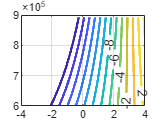

contour(((cgpos)/Cmac)*100,weight*9.81,rad2deg(d_trim),[-18 18],'ShowText','on','LineWidth',3)
grid on;

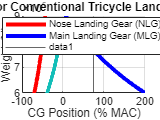

xlabel('CG Position (% MAC)');
ylabel('Weight (N)');
ylim([6e5 9e5])
title('CG Isopleths for Conventional Tricycle Landing Gear Layout');
legend('Nose Landing Gear (NLG)', 'Main Landing Gear (MLG)', 'Location', 'Best');
xline(Xnp_abs_CMAC)
hold off;
